# Range and Speed Using Pulse-Doppler Processing

This example illustrates pulse-Doppler processing using Phased Array System Toolbox™. Assume that you have a stationary monostatic radar located at the global origin, *(0,0,0)*. The radar consists of a single isotropic antenna element. There is a target with a nonfluctuating radar cross section (RCS) of 1 square meter initially located at *(1000,1000,0)* m and moving at a constant velocity of *(-100,-100,0)* m/s. The antenna operates at a frequency of 1 GHz and illuminates the target with 10 rectangular pulses at a PRF of 10 kHz.

**Note:** This example runs only in R2016b or later. If you are using an earlier release, replace each call to the function with the equivalent `step` syntax. For example, replace `myObject(x)` with `step(myObject,x)`.

Define the System objects needed for this example and set their properties. Seed the random number generator for the `phased.ReceiverPreamp` System object™ to produce repeatable results.

clear
fc = 9e9;
c = physconst('LightSpeed');
waveform = phased.RectangularWaveform('SampleRate',5e6,...
    'PulseWidth',6e-7,'OutputFormat','Pulses',...
    'NumPulses',1,'PRF',1e4);
target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',1,'OperatingFrequency',1e9);
targetpos = phased.Platform('InitialPosition',[1000; 3000; 0],...
    'Velocity',[-1000; 2000; 0]);
antenna = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e8 5e9]);
transmitter = phased.Transmitter('PeakPower',5e3,'Gain',20,...
'InUseOutputPort',true);
transpos = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[0;0;0]);
radiator = phased.Radiator('OperatingFrequency',1e9,'Sensor',antenna);
collector = phased.Collector('OperatingFrequency',1e9,'Sensor',antenna);
channel = phased.FreeSpace('SampleRate',waveform.SampleRate,...
    'OperatingFrequency',1e9,'TwoWayPropagation',false);
receiver = phased.ReceiverPreamp('Gain',0,'LossFactor',0,...
    'SampleRate',5e6,'NoiseFigure',5,...
    'EnableInputPort',true,'SeedSource','Property','Seed',1e3);

This loop transmits ten successive rectangular pulses toward the target, reflects the pulses off the target, collects the reflected pulses at the receiver, and updates the target position with the specified constant velocity.

NumPulses = 10;
sig = waveform(); % get waveform 
transpos = transpos.InitialPosition; % get transmitter position
rxsig = zeros(length(sig),NumPulses);
% transmit and receive ten pulses
for n = 1:NumPulses
    % update target position
    [tgtpos,tgtvel] = targetpos(1/waveform.PRF);
    [tgtrng,tgtang] = rangeangle(tgtpos,transpos);
    tpos(n) = tgtrng;
    [txsig,txstatus] = transmitter(sig); % transmit waveform
    txsig = radiator(txsig,tgtang); % radiate waveform toward target
    txsig = channel(txsig,transpos,tgtpos,[0;0;0],tgtvel); % propagate waveform to target
    txsig = target(txsig); % reflect the signal
    % propagate waveform from the target to the transmiter
    txsig = channel(txsig,tgtpos,transpos,tgtvel,[0;0;0]);
    txsig = collector(txsig,tgtang); % collect signal
    rxsig(:,n) = receiver(txsig,~txstatus); % receive the signal
end

The matrix `rxsig` contains the echo data in a 500-by-10 matrix where the row dimension contains the fast-time samples and the column dimension contains the slow-time samples. In other words, each row in the matrix contains the slow-time samples from a specific range bin.

Construct a linearly-spaced grid corresponding to the range bins from the fast-time samples. The range bins extend from 0 meters to the maximum unambiguous range.

prf = waveform.PRF;
fs = waveform.SampleRate;
fasttime = unigrid(0,1/fs,1/prf,'[)');
rangebins = (physconst('LightSpeed')*fasttime)/2;

Next, detect the range bins which contain targets. In this simple scenario, no matched filtering or time-varying gain compensation is utilized.

In this example, set the false-alarm probability to $10^{-9}$. Use noncoherent integration of the ten rectangular pulses and determine the corresponding threshold for detection in white Gaussian noise. Because this scenario contains only one target, take the largest peak above the threshold. Display the estimated target range.

probfa = 1e-9;
NoiseBandwidth = 5e6/2;
npower = noisepow(NoiseBandwidth,...
    receiver.NoiseFigure,receiver.ReferenceTemperature);
thresh = npwgnthresh(probfa,NumPulses,'noncoherent');
thresh = sqrt(npower*db2pow(thresh));
[pks,range_detect] = findpeaks(pulsint(rxsig,'noncoherent'),...
    'MinPeakHeight',thresh,'SortStr','descend');
range_estimate = rangebins(range_detect(1));

Extract the slow-time samples corresponding to the range bin containing the detected target. Compute the power spectral density estimate of the slow-time samples using `periodogram` function and find the peak frequency. Convert the peak Doppler frequency to speed using the `dop2speed` function. A positive Doppler shift indicates that the target is approaching the transmitter. A negative Doppler shift indicates that the target is moving away from the transmitter.

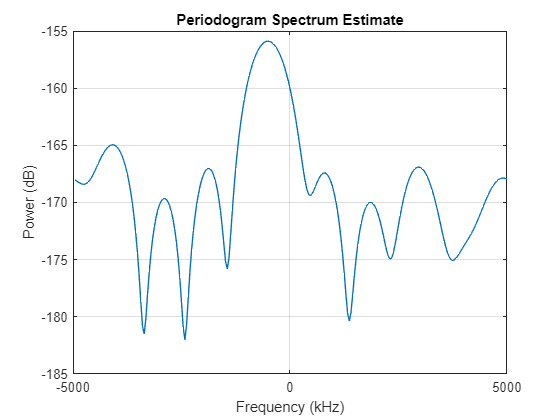

ts = rxsig(range_detect(1),:).';
[Pxx,F] = periodogram(ts,[],256,prf,'centered');
plot(F,10*log10(Pxx))
grid
xlabel('Frequency (kHz)')
ylabel('Power (dB)')
title('Periodogram Spectrum Estimate')

[Y,I] = max(Pxx);
lambda = physconst('LightSpeed')/1e9;
tgtspeed = dop2speed(F(I)/2,lambda);
fprintf('Estimated range of the target is %4.2f meters.\n',...
    range_estimate)

Estimated range of the target is 3177.80 meters.


fprintf('Estimated target speed is %3.1f m/sec.\n',tgtspeed)

Estimated target speed is -76.1 m/sec.


if F(I)>0
    fprintf('The target is approaching the radar.\n')
else
    fprintf('The target is moving away from the radar.\n')
end

The target is moving away from the radar.


The true radial speed of the target is detected within the Doppler resolution and the range of the target is detected within the range resolution of the radar.

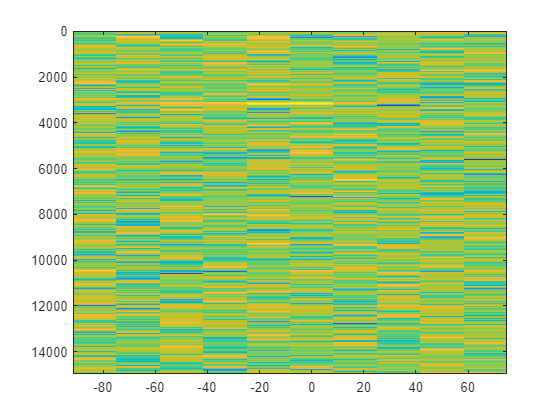

%Create a range-Doppler response object.
rangedopresp = phased.RangeDopplerResponse('SampleRate',fs, ...
    'PropagationSpeed',c,'DopplerOutput','Speed', ...
    'OperatingFrequency',fc,...
    'PRFSource','Property','PRF',prf);
matchingcoeff = getMatchedFilter(waveform);
[rngdopresp,rnggrid,dopgrid] = rangedopresp(rxsig,matchingcoeff);
 im = imagesc(dopgrid,rnggrid,mag2db(abs(rngdopresp)));